T = table2array(readtable(['allArmData.xlsx']));

ref0 = T(:,1);
ref1 = T(:,2);
ref2 = T(:,3);
ref3 = T(:,4);
M0 = T(:,5);
M1 = T(:,6);
M2 = T(:,7);
M3 = T(:,8);

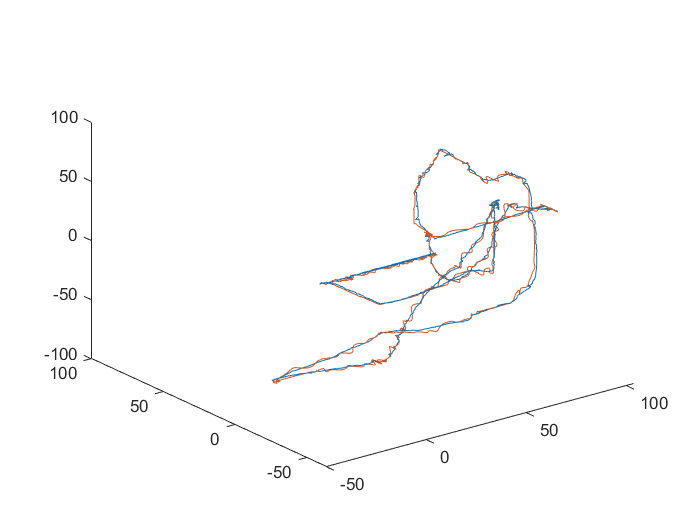

plot3(ref0, ref1, ref2, M0, M1, M2)

refAngs = [ref0 ref1 ref2 ref3];
refAngs = refAngs * pi / 180;
actAngs = [M0 M1 M2 M3];
actAngs = actAngs * pi / 180;

size(refAngs,1)

ans = 1950

refAngs(1,:)

ans =     0.0942   -0.0583    0.0180    1.8286


refPos = zeros(size(refAngs,1),3);
actPos = zeros(size(refAngs,1),3);
error = zeros(size(refAngs,1),1);

for i = 1:size(refAngs,1)
    refPos(i, :) = calcEndEffectorPos(refAngs(i,1), refAngs(i,2), refAngs(i,3), refAngs(i,4));
    actPos(i, :) = calcEndEffectorPos(actAngs(i,1), actAngs(i,2), actAngs(i,3), actAngs(i,4));
    error(i)  = sqrt(sum((refPos(i,:) - actPos(i,:)) .^ 2));
end

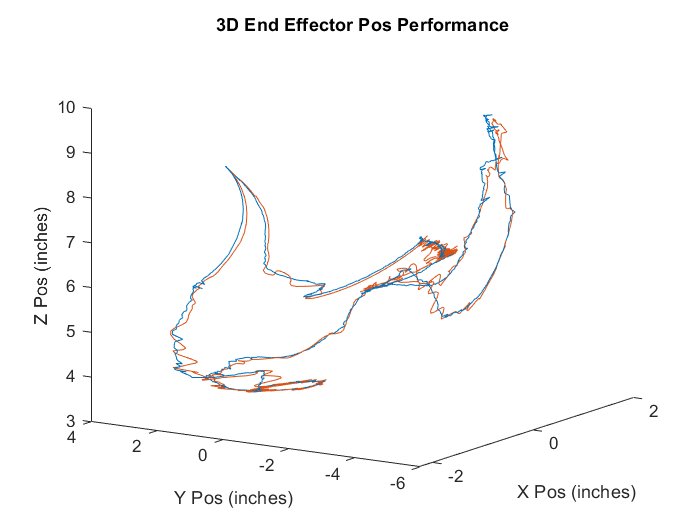

plot3(refPos(:,1), refPos(:,2), refPos(:,3), actPos(:,1), actPos(:,2), actPos(:,3))
title('3D End Effector Pos Performance')
xlabel('X Pos (inches)')
ylabel('Y Pos (inches)')
zlabel('Z Pos (inches)')

view([-56.89 14.81])

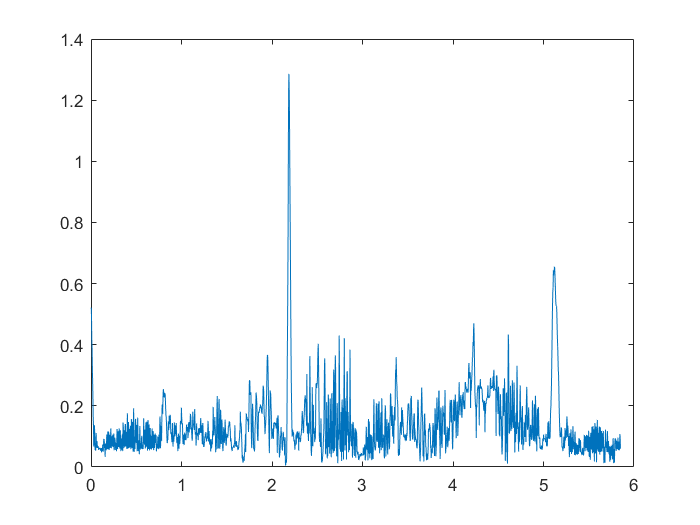

time = (1:size(refAngs,1)) * .003;
plot(time, error)

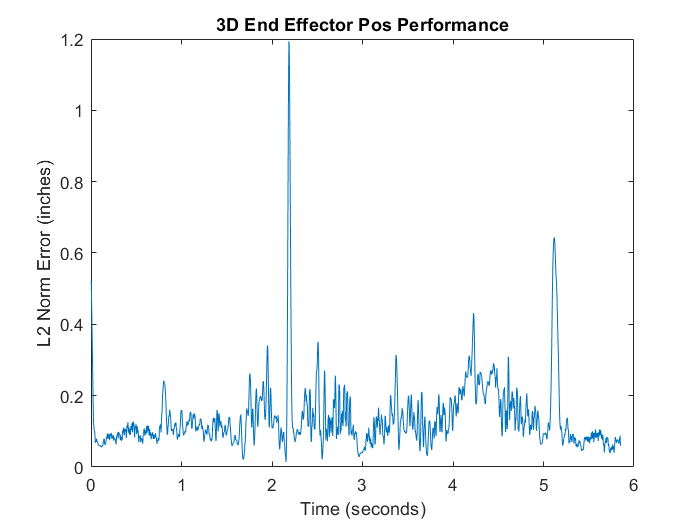

plot(time, smooth(error))
title('3D End Effector Pos Performance')
xlabel('Time (seconds)')
ylabel('L2 Norm Error (inches)')

a = [1;2;3;4];
a(1:3)

ans =      1
     2
     3


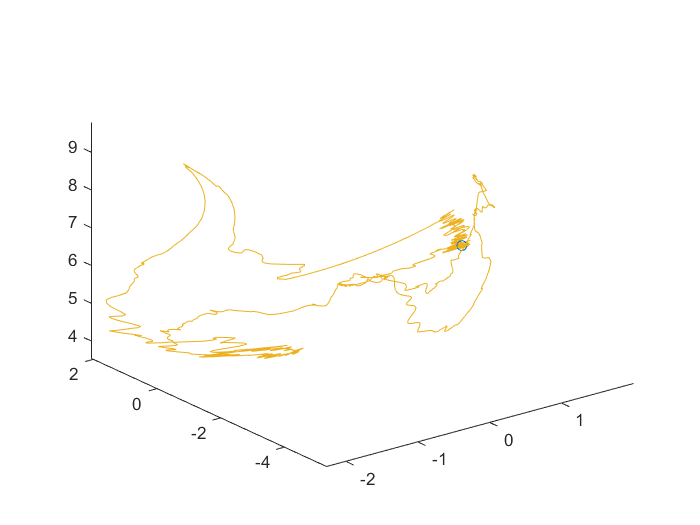

%comet3(refPos(:,1), refPos(:,2), refPos(:,3))
% hold on
comet3(actPos(:,1), actPos(:,2), actPos(:,3))

% hold off

% 
% for i = 1:size(refAngs,1)
%     plot3(refPos(:,1), refPos(:,2), refPos(:,3));
%     plot3(actPos(:,1), actPos(:,2), actPos(:,3));
%     pause(.0001)
% end
5

ans = 5

% for i = 1:size(refAngs,1)
%     plot3(refPos(:,1), refPos(:,2), refPos(:,3));
%     plot3(actPos(:,1), actPos(:,2), actPos(:,3));
%     drawnow
% end